% Lab 3 Task 3a – frequency response measurement
clear all;
ports = serialportlist;
pb = PyBench(ports(end)); % create a PyBench object

pb = pb.set_samp_freq(100);
MIN_F = 1;
MAX_F = 20;
NSTEPS = 19;
fstep = (MAX_F - MIN_F) / NSTEPS;
x_max = 1.55;
x_min = 1.45;
pb = pb.set_max_v(x_max);
pb = pb.set_min_v(x_min);
tic;
for i = 1:NSTEPS
    f = (i-1) * fstep + MIN_F;
    x(i) = f;
    pb = pb.set_sig_freq(f);
    pb.sine();
    pause(2.0);
    data = pb.get_block(200);
    y(i) = 20 * log10((max(data) - min(data)) / (x_max - x_min));
end
toc;

Elapsed time is 93.988588 seconds.


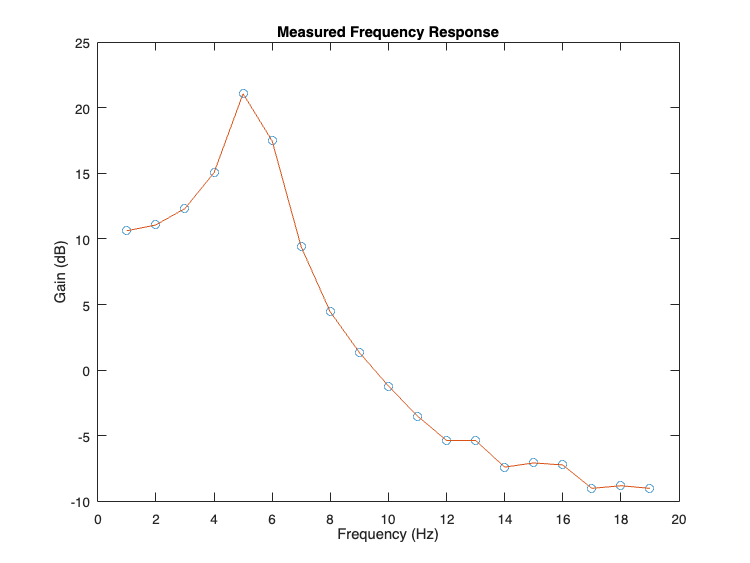

plot(x, y, 'o');
hold on;
plot(x, y);
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
title('Measured Frequency Response');

fclose(instrfind()); % close the port